# Pole Placement Control: Performances

## System Data

clear 
close all
close all

% data for simscape model
% Run this block to initialise simscape pendulum model parameters

% Initial pendulum intial angle in degrees
% 180 corresponds to upright position
% can also be selected in the simulink model
alpha_0=170;

parametri = 1;      % 0 = nominali; 1 = identificati

%% System parameters
if parametri == 0
    B_p = 0.0024; % Pendulum viscous damping coeffi- cient as seen at the pivot axis N*m*s/rad
    B_r = 0.0024; % Rotary arm viscous damping coeffi- cient as seen at the pivot axis N*m*s/rad
    J_a = 0.0020; % Rotary arm moment of inertia about pivot m^2
    J_p = 0.0012; % Pendulum moment of intertia about center of mass Kg*m^2
    l_p = 0.156;  % Distance from pivot to center of mass m
    m_p = 0.127;  % Mass of pendulum Kg
    r = 0.216;    % Rotary arm length from pivot to tip m
    J_T = (J_a*m_p*l_p^2 + J_p*m_p*r^2 + J_a*J_p);
    g = 9.81;     % gravitational acceleration m/s^2

    K_g = 70;      % High-gear total gear ratio
    R_m = 2.6;     % Ohm
    eta_g = 0.90;  % Gearbox efficiency
    eta_m = 0.69;  % Motor efficiency
    k_m = 7.68e-3; % Motor back-emf constant V/(rad/s)
    k_t = 7.68e-3; % Motor current-torque constant N*m/A

    L_p = 0.337; % total length of the vertical pendulum, needed for disturbance modeling
else
    % Valori identificati
    load("th_id.mat")
    B_p = id_param(1); % Pendulum viscous damping coeffi- cient as seen at the pivot axis N*m*s/rad
    B_r = id_param(2); % Rotary arm viscous damping coeffi- cient as seen at the pivot axis N*m*s/rad
    J_a = id_param(3); % Rotary arm moment of inertia about pivot m^2
    J_p = id_param(4); % Pendulum moment of intertia about center of mass Kg*m^2
    l_p = id_param(5);  % Distance from pivot to center of mass m
    m_p = id_param(6);  % Mass of pendulum Kg
    r = id_param(7);    % Rotary arm length from pivot to tip m
    J_T = (J_a*m_p*l_p^2 + J_p*m_p*r^2 + J_a*J_p);
    g = id_param(8);     % gravitational acceleration m/s^2

    K_g = id_param(9);      % High-gear total gear ratio
    R_m = id_param(10);     % Ohm
    eta_g = id_param(11);  % Gearbox efficiency
    eta_m = id_param(12);  % Motor efficiency
    k_m = id_param(13); % Motor back-emf constant V/(rad/s)
    k_t = id_param(14); % Motor current-torque constant N*m/A

    L_p = 0.337; % total length of the vertical pendulum, needed for disturbance modeling
end

voltage_max = 10;
theta_max = 90;     % Maximum theta rotation[deg]
alpha_max = 25;     % Maximum alpha deflection [deg]

## Initial Conditions for Simulations and Simulation Parameters

x0 = [0;0.26;0;0]; % initial state for simulation alpha range in +/- 0.26 rad (+/- 15°)
% x0 = [0;0.09;0;0]; % initial condition of 5°

x0_down = [0;pi;0;0]; % initial condition for the pendulum swing up
Ts = 0.002; % EKF sampling time

## System State Space representation around the unstable equilibrium

% [A,B,C,D] = SS_Matrices_Voltage_Unstable(B_p,B_r,J_T,J_a,J_p,K_g,R_m,eta_g,eta_m,g,k_m,k_t,l_p,m_p,r);
% 
% C_full = eye(4); % we assume to measure the full state of the system
% D_full = zeros(4,1);

[A,B,C,D] = SS_Matrices_Voltage_Unstable_Disturbance(B_p,B_r,J_T,J_a,J_p,K_g,L_p,R_m,eta_g,eta_m,g,k_m,k_t,l_p,m_p,r);
B_d = B(:,2); % disturbance matrix
B_u = B(:,1); % input matrix
C_full = eye(4);
D_full = zeros(4,size(B,2));
D_full_u = D_full(:,1);

**Remark: **In simulation, always use the system with full state!!! In this way you can see also the simulation of the states that in the real setup are not measurable.

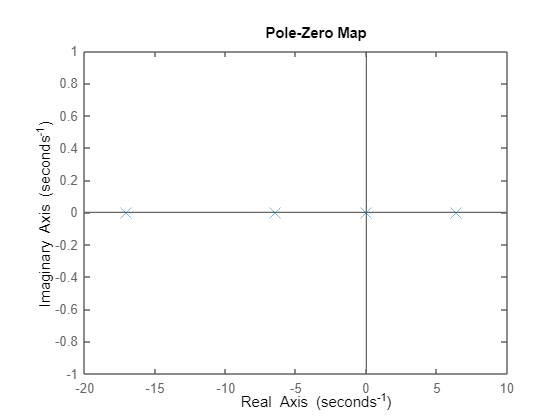

sys_ol = ss(A,B_u,C_full,D_full_u); % open loop system

figure(1);
pzmap(sys_ol)
set(findobj(gca, 'type', 'line'), 'MarkerSize', 12);

We can see the presence of:

- An unstable real pole

- A zero at the origin

poli = pole(sys_ol)

poli =          0
    6.4075
   -6.4233
  -17.0228


zeri = tzero(sys_ol)


zeri =

  0×1 empty double column vector



## Pole Placement Controller Design: Stability

We want first to design a pole placement controller able to stabilize the pendulum around the vertical position.

We'll assume that the full state is measurable.

% Compute the reachability matrix for the pair (A, B)
n = size(A,1) % order of the system 

n = 4

m = size(B_u,2) % input dimension

m = 1

p = size(C,1) % measured_output dimension

p = 2

We check that the pair of the system we want to control is **reachable:**

M_r = ctrb(A, B_u); % this function computes the reachabiltiy matrix of the system
rank(M_r) == n % we compute the rank of Mr and compare it to the order of the system -> number of states

ans = logical
   1


### Chosing the poles positions

We stabilize the system and make it behave as a 2nd order system with a cutoff frequency of 5rad/s almost.

% pp_desired_poles = [-5 -5.1 -15 -15.1];
pp_desired_poles = [-8.4+12i -8.4-12i -11 -11.001]; % lab values, not robust but fast
Kpp = place(A, B_u, pp_desired_poles)

Kpp =   -22.4860   56.6991   -6.6980    8.0272


We then want to compare the singular values of the stabilized loop with the open loop ones:

% sys_cl_pp = ss(A - B_u * Kpp, B_u, C_full, D_full_u); % we define a ss representation

## Observer Design

In this section the design of a full order observer is performed.

First we verify that the system for which we want to design the observer is **observable**, aka that we have a sufficient number of sensors:

M_o = obsv(A, C);
rank(M_o) == n

ans = logical
   1


% obsv_poles = [-90, -90.1, -55+50i, -55-50i];
% obsv_poles = [-60,-60.1,-70,-70.1];
obsv_poles = [-40-4i, -40+4i, -50+5i, -50-5i]; % lab values

Introducing complex conjugate poles allowed to reduce the inverse response of the observer.

L_obs = place(A', C', obsv_poles)'

L_obs = 1.0e+03 *

    0.0730   -0.0015
   -0.0158    0.0900
    0.8119   -0.0111
   -1.2200    2.0502


A_ob = A - L_obs*C;
B_ob = [B_u - L_obs*D, L_obs];
C_ob = eye(n);
D_ob = zeros(n, m+p);
% initial conditions for observer
x0_ob = [0;0;0;0];

% sys_obs = ss(A_ob,B_ob,C_ob,D_ob);
% obs_poles = pole(sys_obs)
% obs_zeros = tzero(sys_ol)
% figure(4);
% pzmap(sys_obs)
% set(findobj(gca, 'type', 'line'), 'MarkerSize', 12);
% figure(5);
% sigma(sys_obs); % we compute eigs
% set(findobj(gca, 'type', 'line'), 'LineWidth', 2);

## Tracking

### Full-State Controller Performances

In order to track a given reference we need to enlarge the system by introducing integrators. In particular we'll add a number of integrators equal to the number of output that we want to track.

We know that **the system to be controlled has no derivative action since there's no zero**. So we can effectively introduce integrators to achieve performances of the control system.

However we have that the number of output is greater than the number of inputs: $p>m$.

So we first need to consider the reduced order system and check if:

- $p\le m$ which is always verified when dealing with a scalar system

- there's no zero with derivative action: $s\not= 0\;$in $N\left(s\right)$.

### $G_{V\alpha \;} \left(s\right)$:

We compute the transfer function of the open loop system from the input to the alpha angle.

- $p=m$ is verified since the system is scalar

G_sys_ol = tf(sys_ol);

G_alpha = G_sys_ol(2)

G_alpha =
 
         25.42 s - 1.497e-14
  ---------------------------------
  s^3 + 17.04 s^2 - 40.89 s - 700.6
 
Continuous-time transfer function.



zero(G_alpha)

ans = 5.8878e-16

We can see **there's a zero very close to the origin**, this imply that we cannot control the alpha angle through our input.

### $G_{V\theta \;} \left(s\right)$:

Now we repeat for the transfer function from the voltage to the horizontal arm angle:

G_theta = G_sys_ol(1)

G_theta =
 
       27.22 s^2 + 12.45 s - 1155
  -------------------------------------
  s^4 + 17.04 s^3 - 40.89 s^2 - 700.6 s
 
Continuous-time transfer function.



zero(G_theta)

ans =    -6.7456
    6.2884


We can see no zero is present in this transfer function, aka the state is controllable toward constant reference values.

### System Enlargement

The state space matrices of the enlarged system are:

pc = 1; % number of controllable outputs

A_tilde = [A zeros(n,pc);
           -C(1,:) zeros(pc)];
B_tilde = [B_u;
           zeros(pc)];
M_tilde = [zeros(n,pc);
           eye(pc)];

### Pole Placement Controller Design for the enlarged system

We need to decide where to place the poles for this system.

We can start by considering that we expect a fast dynamics associated to the stabilization of the pendulum and a slower dynamics associated to the control of the position of the horizontal arm.

We can look first at the natural frequency of the pendulum in the down position:

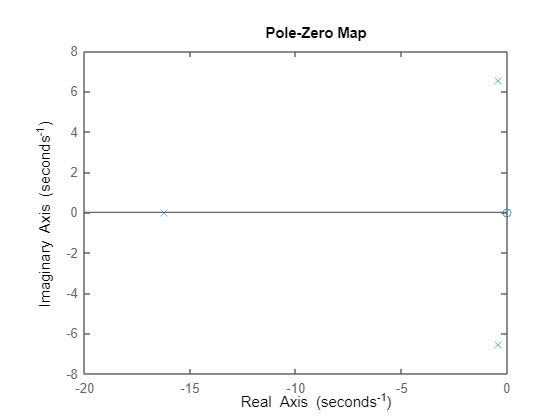

[A_down,B_down,C_down,D_down] = SS_Matrices_Voltage_Stable(B_p,B_r,J_T,J_a,J_p,K_g,R_m,eta_g,eta_m,g,k_m,k_t,l_p,m_p,r);
C_down = eye(4); % full state feedback
D_down = zeros(4,1);

sys_down = ss(A_down,B_down,C_down,D_down);
tf_sys_down = tf(sys_down);
tf_sys_down_alpha = tf_sys_down(2);
pzmap(tf_sys_down_alpha)

From this map we can see that for the transfer function from the voltage to the alpha angle the doinant poles are a complex conjugate pair.

Now we proceed to compute the natural frequency and the damping ratio of these poles.

damp(tf_sys_down_alpha)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -3.96e-01 + 6.55e+00i     6.03e-02       6.57e+00         2.52e+00    
 -3.96e-01 - 6.55e+00i     6.03e-02       6.57e+00         2.52e+00    
 -1.62e+01                 1.00e+00       1.62e+01         6.16e-02    


We can see that the 2 c.c. poles have a natural frequency of $6\ldotp 57\;\frac{\textrm{rad}}{s}$. That's approximately the natural frequency of the pendulum.

We try to place 2 poles at $\lambda_{1,2} =-\zeta \;\omega {\;}_n \pm {j\omega }_n$. Choosing a $\zeta =0\ldotp 7\;$to reduce both the overshoot and have a fast rise time.

For the control of theta, we choose $\zeta =1$ to provide a zero overshoot and a natural frequency that allow to get a sufficiently fast rise time with respect to the unitary step

%en_desired_poles = [-3.3-6.57i -3.3+6.57i -1.54-2.2i  -1.54+2.2i, -20];

% en_desired_poles = [-6-9i -6+9i -7 -7.001, -15]; % this one

% en_desired_poles = [-8.5-17i -8.5+17i -6.3+9i -6.3-9i, -20]; % not bad
% en_desired_poles = [-7.5-15i -7.5+15i -8 -8.1, -20]; % up to now the best one
% en_desired_poles = [-10.5-15i -10.5+15i -8 -8.1, -20];
% en_desired_poles = [-11.9-17i -11.9+17i -9 -9.1, -20];

en_desired_poles = [-4.9-7i -4.9+7i -5 -5.001, -15]; % In the lab

We set randomly the poles of integrators, recalling that we never use pure integrators but first order systems !!!

Ken = place(A_tilde, B_tilde, en_desired_poles)

Ken =   -14.5054   38.8387   -4.7133    5.7450   23.7158


Then split the gain as $K_{\textrm{en}} =\left\lbrack \begin{array}{cc}
K_{\textrm{en},x}  & K_{\textrm{en},\eta \;} 
\end{array}\right\rbrack \;$such that $u=-K_{\textrm{en}} \;\tilde{x} =-K_{\textrm{en},x} \;\hat{x} -K_{\textrm{en},\eta \;} \eta \;$

Note that we don't need to redesign a state obserever since we can use the one previously designed.

Ken_x = Ken(:, 1:n); % control of original system states
Ken_eta = Ken(:, n+1:end); % control of integrators states

# LQG Control Design

## LQG Stability

### Defining the design parameters

Recall that Q > R allow to have a faster closed loop system

voltage_max_R = 10;
theta_max_Q = theta_max*pi/180     % Maximum theta rotation[deg]

theta_max_Q = 1.5708

alpha_max_Q = alpha_max*pi/180     % Maximum alpha deflection [deg]

alpha_max_Q = 0.4363

### Assigning a prescribed rate of convergence to the closed loop 

we can  proceed by considering a parameter $\alpha \;$to define the prescribed minimum frequency of the closed loop poles.

q_theta = 0.1;
q_alpha = 1;
r_voltage =50;
Q_lq = diag([q_theta/theta_max_Q^2, q_alpha/alpha_max_Q^2, 0.001/5^2, (1e-3)/5^2])

Q_lq =     0.0405         0         0         0
         0    5.2525         0         0
         0         0    0.0000         0
         0         0         0    0.0000


R_lq = r_voltage/voltage_max_R^2

R_lq = 0.5000


alpha = 5; % 8 rad/s as in the pole placement final performances
A_tilde = A + alpha*eye(4);
% controller gain
K_lq_alpha = lqr(A_tilde, B_u, Q_lq, R_lq)

K_lq_alpha =   -20.6641   66.5292   -7.8383    9.7669


sys_cl_lq_alpha= ss(A-B_u*K_lq_alpha,zeros(4,1),C_full,D_full_u);
poli = pole(sys_cl_lq_alpha)

poli =  -17.0032 + 3.1951i
 -17.0032 - 3.1951i
 -10.0463 + 0.0000i
  -7.9349 + 0.0000i


### Kalman Filter: Linear Quadratic Observer

Here we want to design a Kalman Filter for our problem and compare its performances with respect to the previous observer.

**Side Note: **Since our system is MIMO but not square, ($m\not= p$), we cannot apply the loop transfer recovery to ensure robustness of the LQ control law.

We design here a full state KF

#### Not considering cross correlation between input and output: (simplifying Hypothesis)

Recall that when Q > R it means that the sensors are good and we trust them more than the model.

We can place more weight on the Q terms associated with the theta and alpha angle because we trust more the measurements wrt the model for those variables, instead we need to set lower the terms associated to the speed since the model is the only way we can effectively know those variables.

Q_kf = diag([9,8,7.5e3,3.7e3]); % we are going to set model variance quite low because we have a good model
R_kf = diag([3e-3,1.5e-3]); % since our sensors are quite good, thus we really trust them

% recall: Q/R higher means the filter will be faster
rank(obsv(A, C))

ans = 4

B_qkf = sqrt(Q_kf);
rank(ctrb(A, B_qkf));

% kf gain
L_kf = lqr(A', C', Q_kf, R_kf)';
A_kf = A - L_kf * C;
B_kf = [ B_u, L_kf ];
C_kf = eye(4);
D_kf = zeros(4, 3);
sys_kf = ss(A_kf,B_kf,C_kf,D_kf);
poli_kf = pole(sys_kf)

poli_kf =  -34.2773 + 0.0000i
 -36.7218 + 8.3918i
 -36.7218 - 8.3918i
 -70.5291 + 0.0000i


## LQG: Tracking

## Tracking Performances through Integrators

The arguments are analogous to the ones reported in the Pole Placement control section. So we go straight-forward to the system enlargement

pc = 1; % number of controllable outputs

A_tilde_tilde = [A zeros(n,pc);
           -C(1,:) zeros(pc)];
B_tilde = [B_u;
           zeros(pc)];
M_tilde = [zeros(n,pc);
           eye(pc)];

### LQ Controller Design for the augmented system

% Compute the reachability matrix for the pair (A, B)
n = size(A_tilde_tilde,1); % order of the system 
m = size(B_tilde,2); % input dimension
p = size(C,1); % measured_output dimension

M_r = ctrb(A_tilde_tilde, B_tilde); % this function computes the reachabiltiy matrix of the system
rank(M_r) == n % we compute the rank of Mr and compare it to the order of the system -> number of states

ans = logical
   1


voltage_max_R = 10;         % Maximum Voltage [V]
theta_max_Q = theta_max*pi/180     % Maximum theta rotation[deg]

theta_max_Q = 1.5708

alpha_max_Q = alpha_max*pi/180     % Maximum alpha allowed for control

alpha_max_Q = 0.4363

### Assigning a prescribed rate of convergence to the closed loop 

we can  proceed by considering a parameter $\alpha \;$to define the prescribed minimum frequency of the closed loop poles.

q_theta = 1e-3*theta_max_Q^2;
q_alpha = 1e0*alpha_max_Q^2;
r_voltage = 0.1*voltage_max_R^2;
Q_lq_tilde = diag([q_theta/theta_max_Q^2, q_alpha/alpha_max_Q^2, 1e-3*5^2/5^2, 1e-3*5^2/5^2, 1e-4])

Q_lq_tilde =     0.0010         0         0         0         0
         0    1.0000         0         0         0
         0         0    0.0010         0         0
         0         0         0    0.0010         0
         0         0         0         0    0.0001


R_lq_tilde = r_voltage/voltage_max_R^2

R_lq_tilde = 0.1000


alpha = 2; % 8 rad/s as in the pole placement final performances
A_tilde = A_tilde_tilde + alpha*eye(5);
% controller gain
K_lq_en_alpha = lqr(A_tilde, B_tilde, Q_lq_tilde, R_lq_tilde)

K_lq_en_alpha =   -13.8752   45.5579   -5.3168    6.7078   16.8944


sys_cl_lq_en_alpha= ss(A_tilde_tilde-B_tilde*K_lq_en_alpha,zeros(5,1),eye(5),zeros(5,1));
poli = pole(sys_cl_lq_en_alpha)

poli =  -15.3798 + 0.0000i
 -13.6816 + 0.0000i
  -5.7806 + 0.0000i
  -4.0047 + 0.0145i
  -4.0047 - 0.0145i


What was working for stabilization:

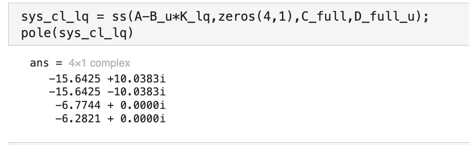

### Observer for the augmented system

For what concern the observer, we can just use the previously designed one, for the stabilization problem.

K_lq_en_alpha_x = K_lq_en_alpha(:, 1:n-1) % control of original system states

K_lq_en_alpha_x =   -13.8752   45.5579   -5.3168    6.7078


K_lq_en_alpha_eta = K_lq_en_alpha(:, n) % control of integrators states

K_lq_en_alpha_eta = 16.8944

# Swing Up Controller Design

## Coefficients of torque-voltage relationship

c1_tau = (K_g*eta_g*eta_m*k_t)/R_m;

## Coefficient of Linearizing Torque

Jp_prime = (m_p*l_p^2 + J_p);
% J_a + m_p*r^2 + l_p^2*m_p*sin(alpha_t)^2 - (l_p^2*m_p^2*r^2*cos(alpha_t)^2)/(m_p*l_p^2 + J_p) % theta_ddot_d
% (l_p*m_p*r*sin(alpha_t)) % alpha_dot^2 coeff.
% (l_p^2*m_p*sin(2*alpha_t)) % alpha_dot*theta_dot coeff
% (-(l_p^3*m_p^2*r*cos(alpha_t)^2*sin(alpha_t))/(m_p*l_p^2 + J_p)) %theta_dot^2 coeff
%  - (g*l_p^2*m_p^2*r*cos(alpha_t)*sin(alpha_t))/(m_p*l_p^2 + J_p) %  gravity compensation

## Gains for energy control  and PD Control on Theta

K_energy = 1000*(1/l_p*m_p*r);
Kp = 100;
Kd = 2;

## EKF Design

%% EKFilter Parameters
% initial state, quat. components will be taken later from the first
% measurement of Aruco
x0_KF = [0;pi;0;0]; % initial states
P0 = eye(4); % initial covariance (10 states)

% Cov. are managed by scalar hyperparameters (rho) that multiply all the cov. values
% associated to a measure device (zedM,2 and Aruco) for convenience.
% In this way coarse tuning can be performed by changing 1 value insted of
% 3 (one for each axis)

% measurement covariances - the greater the worse the sensor
rho_theta_meas = 1e-3;
rho_alpha_meas = 1e-3;

% process covariances
rho_theta_process = 0.01;
rho_alpha_process = 0.01;
rho_theta_dot_process = 2e3;
rho_alpha_dot_process = 2e3;

% define now value of covariances for each component, scaled by RHOs
% defined above

Cov_theta = 1*rho_theta_meas;
Cov_alpha = 1*rho_alpha_meas;

Cov_theta_process = 1*rho_theta_process;
Cov_alpha_process = 1*rho_alpha_process;
Cov_theta_dot_process = 1*rho_theta_dot_process;
Cov_alpha_dot_process = 1*rho_alpha_dot_process;

R = diag([Cov_theta; Cov_alpha]); % MEASUREMENT MATRIX 
E = diag([Cov_theta_process;Cov_alpha_process;Cov_theta_dot_process;Cov_alpha_dot_process]);  % PROCESS MATRIX